# Inverse Kinematic in Body Form and Space Form

clc; clear;

#### Define Panda Robot

panda_model()

#### Defining Matrix M

vpa(M, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.088\\ 0 & -1.0 & 0 & 0\\ 0 & 0 & -1.0 & 0.926\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### Screw axes expresssed in {s} frame at home configuration

vpa(S, 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 & 0 & 1.0 & 0 & -1.0\\ 0 & -0.333 & 0 & 0.649 & 0 & 1.033 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.088\\ 0 & 0 & 0 & -0.0825 & 0 & 0 & 0 \end{array}\right)$$

#### Screw axes expresssed in {b} frame at home configuration

vpa(B, 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & -1.0 & 0 & 1.0 & 0 & 1.0 & 0\\ -1.0 & 0 & -1.0 & 0 & -1.0 & 0 & 1.0\\ 0 & 0.593 & 0 & -0.277 & 0 & 0.107 & 0\\ -0.088 & 0 & -0.088 & 0 & -0.088 & 0 & 0\\ 0 & 0.088 & 0 & -0.0055 & 0 & -0.088 & 0 \end{array}\right)$$

#### Define an arbitrary configuration to compute IK and FK

Theta = panda.qlim(:, 1) + rand(7, 1).*(panda.qlim(:, 2) - panda.qlim(:, 1));

vpa(Theta', 4)

$$ans = \left(\begin{array}{ccccccc} -2.469 & 0.649 & -0.5656 & -0.1213 & -0.5668 & 2.322 & -2.003 \end{array}\right)$$

#### Forward Kinematic in Body Form

Tb = FK_BodyForm(B, M, Theta);
vpa(Tb, 4)

$$ans = \left(\begin{array}{cccc} -0.2872 & -0.01065 & -0.9578 & -0.4675\\ -0.42 & -0.8973 & 0.1359 & -0.3082\\ -0.8609 & 0.4413 & 0.2533 & 0.9664\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### Forward Kinematic in Space Form

Ts = FK_SpaceForm (S, M, Theta);
vpa(Ts, 4)

$$ans = \left(\begin{array}{cccc} -0.2872 & -0.01065 & -0.9578 & -0.4675\\ -0.42 & -0.8973 & 0.1359 & -0.3082\\ -0.8609 & 0.4413 & 0.2533 & 0.9664\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### Forward Kinematic in Robot Model

Tm = fkine(panda, Theta);
vpa(double(Tm), 4)

$$ans = \left(\begin{array}{cccc} -0.2872 & -0.01065 & -0.9578 & -0.4675\\ -0.42 & -0.8973 & 0.1359 & -0.3082\\ -0.8609 & 0.4413 & 0.2533 & 0.9664\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### Importing Robot from URDF

robot = importrobot('Franka_Emika_Panda.urdf');

#### Initial Guess for an Arbitrary Config

theta0 = panda.qlim(:, 1) + rand(7, 1).*(panda.qlim(:, 2) - panda.qlim(:, 1));
vpa (theta0', 5)

$$ans = \left(\begin{array}{ccccccc} -0.73265 & -1.4543 & 0.81192 & -2.5296 & -2.6362 & 2.7089 & -0.88404 \end{array}\right)$$

#### IK Body Form

Qb = IK_BodyForm(Tb, theta0, [1e-5, 1e-5], B, M);
vpa(Qb', 5)

$$ans = \left(\begin{array}{ccccccc} -2.1523 & 0.30598 & -0.64928 & -0.74171 & -0.99407 & 2.4948 & -1.7163 \end{array}\right)$$

#### IK Space Form

Qs = IK_SpaceForm(Ts, theta0, [1e-5, 1e-5], S, M);
vpa(Qs', 5)

$$ans = \left(\begin{array}{ccccccc} -2.1523 & 0.30598 & -0.64928 & -0.74171 & -0.99407 & 2.4948 & -1.7163 \end{array}\right)$$

#### Check IK Body Form

Tb1 = FK_BodyForm(B, M, Qb);
IK_BodyForm_Result = vpa(Tb1, 5)

$$IK\_BodyForm\_Result = \left(\begin{array}{cccc} -0.28771 & -0.01018 & -0.95766 & -0.46731\\ -0.42005 & -0.89729 & 0.13573 & -0.30814\\ -0.86069 & 0.44131 & 0.25389 & 0.96658\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### Check IK Space From

Ts1 = FK_SpaceForm(S, M, Qs);
IK_SpaceForm_Result = vpa(Ts1, 5)

$$IK\_SpaceForm\_Result = \left(\begin{array}{cccc} -0.28771 & -0.01018 & -0.95766 & -0.46731\\ -0.42005 & -0.89729 & 0.13573 & -0.30814\\ -0.86069 & 0.44131 & 0.25389 & 0.96658\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

IK_SpaceForm_Error = vpa(Ts1-Ts, 4)

$$IK\_SpaceForm\_Error = \left(\begin{array}{cccc} -0.0004774 & 0.0004677 & 0.0001382 & 0.0001497\\ -7.234e-5 & 5.47e-6 & -0.0001876 & 1.483e-5\\ 0.0001947 & 2.216e-5 & 0.0006225 & 0.0001572\\ 0 & 0 & 0 & 0 \end{array}\right)$$

IK_BodyForm_Error = vpa(Tb1-Tb, 4)

$$IK\_BodyForm\_Error = \left(\begin{array}{cccc} -0.0004774 & 0.0004677 & 0.0001382 & 0.0001497\\ -7.234e-5 & 5.47e-6 & -0.0001876 & 1.483e-5\\ 0.0001947 & 2.216e-5 & 0.0006225 & 0.0001572\\ 0 & 0 & 0 & 0 \end{array}\right)$$

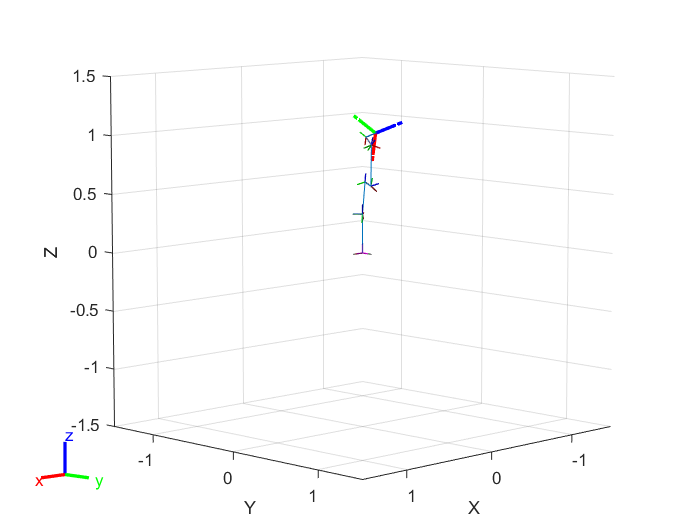


robot.DataFormat = 'column';
show(robot,Theta,'Visuals','off');
hold on;
triad('Matrix',Ts1,'Scale',0.3,'LineWidth',2,'linestyle','-.');
triad('Matrix',Tb1,'Scale',0.2,'LineWidth',2 ,'linestyle','-');